# Examining the effect of noise

clear; close all; clc;
database = load('database/database.mat').database;
path = 'test_musics/'; % test musics path
song_num = 11; % music i
format = '.wav';
[downsampled_Fs, audioMono] = import_audio(path, song_num, format);
noise=randn(size(audioMono))/10;
initial_snr=sum(audioMono.^2)/sum(noise.^2);
SNR=[10:-1:2,1:-0.2:0.4,0.2:-0.01:0.01];
for k=1:length(SNR)
    snr=SNR(k);
    audioMono_1=audioMono*sqrt(snr/initial_snr)+noise;
    window_time = 0.1;
    [time, freq, time_freq_mat] = STFT(audioMono_1, downsampled_Fs, window_time);
    df = floor(0.1*size(time_freq_mat, 1)/4);
    dt = 2/window_time;
    anchor_points = find_anchor_points(time_freq_mat, dt, df);
    df_hash = floor(0.1*size(time_freq_mat,1));
    dt_hash = 20/window_time;
    [hash_key, hash_value] = create_hash_tags(anchor_points, df_hash, dt_hash, 0);
    list = []; 
    for i = 1:length(hash_key)
        key_tag = [num2str(hash_key(i, 1)), '*', num2str(hash_key(i, 2)), '*', num2str(hash_key(i, 3))];
        if (isKey(database, key_tag))
            temp1 = split(database(key_tag),'+');
            for j = 1:length(temp1)
                temp2 = split(temp1{j},'*');
                list = [list; [str2num(temp2{1}),str2num(temp2{2}),hash_value(i,2)]];
            end
        end
    end
    scoring_with_snr(list,snr);
end

First possibility when SNR = 10:
36 - 0.99886 - ZAZ - Je Veux
First possibility when SNR = 9:
36 - 0.99886 - ZAZ - Je Veux
First possibility when SNR = 8:
36 - 0.99824 - ZAZ - Je Veux
First possibility when SNR = 7:
36 - 0.99728 - ZAZ - Je Veux
First possibility when SNR = 6:
36 - 0.99728 - ZAZ - Je Veux
First possibility when SNR = 5:
36 - 0.99643 - ZAZ - Je Veux
First possibility when SNR = 4:
36 - 0.99424 - ZAZ - Je Veux
First possibility when SNR = 3:
36 - 0.99268 - ZAZ - Je Veux
First possibility when SNR = 2:
36 - 0.98812 - ZAZ - Je Veux
First possibility when SNR = 1:
36 - 0.91059 - ZAZ - Je Veux
First possibility when SNR = 0.8:
36 - 0.87233 - ZAZ - Je Veux
First possibility when SNR = 0.6:
36 - 0.82968 - ZAZ - Je Veux
First possibility when SNR = 0.4:
36 - 0.61605 - ZAZ - Je Veux
First possibility when SNR = 0.2:
36 - 0.4134 - ZAZ - Je Veux
First possibility when SNR = 0.19:
36 - 0.26508 - ZAZ - Je Veux
First possibility when SNR = 0.18:
36 - 0.30084 - ZAZ - Je Veux
First poss

Now we choose 50 different 10 seconds long snippets of audio from a song, add noise with different SNRs to it and see how it affects our true detection probability

clear; close all; clc;
database = load('database/database.mat').database;
path = 'musics/'; % musics path
song_num = 36;
format = '.mp3';
[downsampled_Fs, audioMono11] = import_audio(path, song_num, format);
ten_sec_starts=randsample(length(audioMono11)-10*downsampled_Fs,50);
SNR=[10:-1:2,1:-0.2:0.4,0.2:-0.05:0.05];
probs=zeros(1,length(SNR));
for k=1:length(SNR)
    snr=SNR(k);
    for l=1:50
        audioMono=audioMono11(ten_sec_starts(l):ten_sec_starts(l)+10*downsampled_Fs);
        noise= randn(size(audioMono))/10; 
        initial_snr=sum(audioMono.^2)/sum(noise.^2);
        audioMono=audioMono*sqrt(snr/initial_snr)+noise;
        
        window_time = 0.1;
        [time, freq, time_freq_mat] = STFT(audioMono, downsampled_Fs, window_time);
        df = floor(0.1*size(time_freq_mat, 1)/4);
        dt = 2/window_time;
        anchor_points = find_anchor_points(time_freq_mat, dt, df);
        df_hash = floor(0.1*size(time_freq_mat,1));
        dt_hash = 20/window_time;
        [hash_key, hash_value] = create_hash_tags(anchor_points, df_hash, dt_hash, 0);
        list = []; 
        for i = 1:length(hash_key)
            key_tag = [num2str(hash_key(i, 1)), '*', num2str(hash_key(i, 2)), '*', num2str(hash_key(i, 3))];
            if (isKey(database, key_tag))
                temp1 = split(database(key_tag),'+');
                for j = 1:length(temp1)
                    temp2 = split(temp1{j},'*');
                    list = [list; [str2num(temp2{1}),str2num(temp2{2}),hash_value(i,2)]];
                end
            end
        end
        prob=new_scoring(list,song_num);
        probs(k)=prob/50+probs(k);
    end
    fprintf(['For SNR = ',num2str(snr),' The Average Probability of True Detection of the Song is ', num2str(probs(k)), '\n']);
end

For SNR = 10 The Average Probability of True Detection of the Song is 0.82873
For SNR = 9 The Average Probability of True Detection of the Song is 0.82814
For SNR = 8 The Average Probability of True Detection of the Song is 0.82734
For SNR = 7 The Average Probability of True Detection of the Song is 0.80948
For SNR = 6 The Average Probability of True Detection of the Song is 0.81993
For SNR = 5 The Average Probability of True Detection of the Song is 0.80732
For SNR = 4 The Average Probability of True Detection of the Song is 0.79611
For SNR = 3 The Average Probability of True Detection of the Song is 0.80069
For SNR = 2 The Average Probability of True Detection of the Song is 0.76532
For SNR = 1 The Average Probability of True Detection of the Song is 0.73876
For SNR = 0.8 The Average Probability of True Detection of the Song is 0.71198
For SNR = 0.6 The Average Probability of True Detection of the Song is 0.67933
For SNR = 0.4 The Average Probability of True Detection of the Song is 

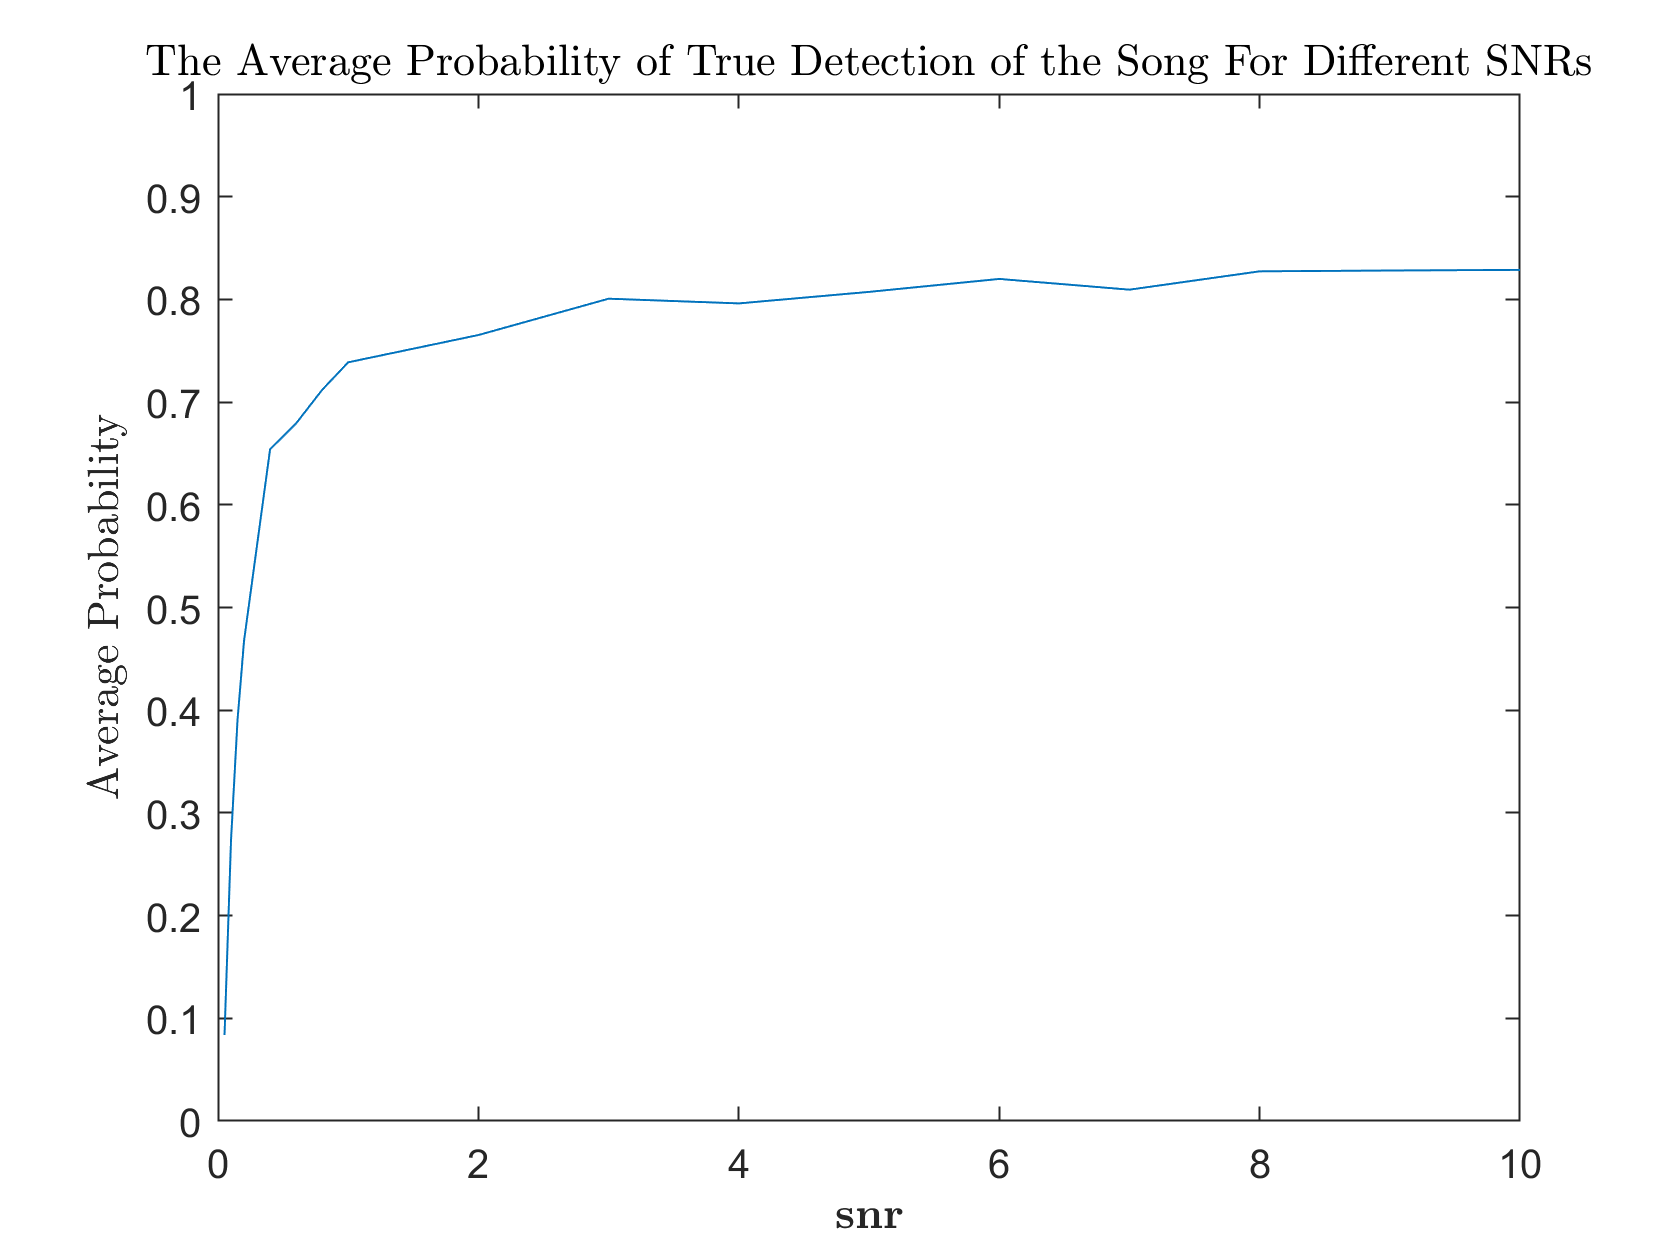

plot(SNR,probs);
title('The Average Probability of True Detection of the Song For Different SNRs','Interpreter','latex');
xlabel('\textbf{snr}','Interpreter','latex');
ylabel('Average Probability','Interpreter','latex');
ylim([0,1]);

Altered scoring function

function score= scoring_with_snr(list,snr)
    if ~isempty(list) % similarity length != 0
        matched_musics = unique(list(:,1)); % musics which for similarity is found
        score = zeros(length(matched_musics),2); % music name - repetition num
        eps = 0.1;
        for i = 1:length(matched_musics)
            temp = list(list(:,1) == matched_musics(i),:); 
            num = length(temp); % number of repeats for music i
            standard_dev = std(temp(:,2)-temp(:,3))/max(temp(:,2)-temp(:,3));
            score(i, 1) = matched_musics(i); % music name
            % score formula (using repetition num and std of delta ts)
            score(i, 2) = log10(num)*(1-exp((1-num)/10))*(1/(standard_dev+eps)); 
        end
        % applying softmax function to get probability distribution
        score(:, 2) = exp(score(:,2))./sum(exp(score(:,2)));
        % sorting based on scores
        [~, permutation] = sort(score(:, 2),'descend');
        score = score(permutation, :);
        songs_names = load('database/songs_names.mat').songs_names;
        fprintf(['First possibility when SNR = ',num2str(snr),':\n']);
        fprintf([num2str(score(1,1)),' - ', num2str(score(1,2)),...
                ' - ', songs_names{score(1,1)}, '\n']);
    else
        fprintf('list cannot be empty');
    end
end

Slightly different scoring function

function prob= new_scoring(list,song_num)
    if ~isempty(list) % similarity length != 0
        matched_musics = unique(list(:,1)); % musics which for similarity is found
        score = zeros(length(matched_musics),2); % music name - repetition num
        eps = 0.1;
        for i = 1:length(matched_musics)
            temp = list(list(:,1) == matched_musics(i),:); 
            num = length(temp); % number of repeats for music i
            standard_dev = std(temp(:,2)-temp(:,3))/max(temp(:,2)-temp(:,3));
            score(i, 1) = matched_musics(i); % music name
            % score formula (using repetition num and std of delta ts)
            score(i, 2) = log10(num)*(1-exp((1-num)/10))*(1/(standard_dev+eps)); 
        end
        % applying softmax function to get probability distribution
        score(:, 2) = exp(score(:,2))./sum(exp(score(:,2)));
        prob=score(score(:,1)==song_num,2);
        %fprintf([num2str(score(1,1)),' - ', num2str(score(1,2)),...
        %        ' - ', songs_names{score(1,1)}, '\n']);
    else
        fprintf('list cannot be empty');
    end
end